# Activity 7: Feature Extraction from Labeled Blobs

#### Submitted by: Jonabel Eleanor B. Baldres

#### App Physics 157 WFY FX 2

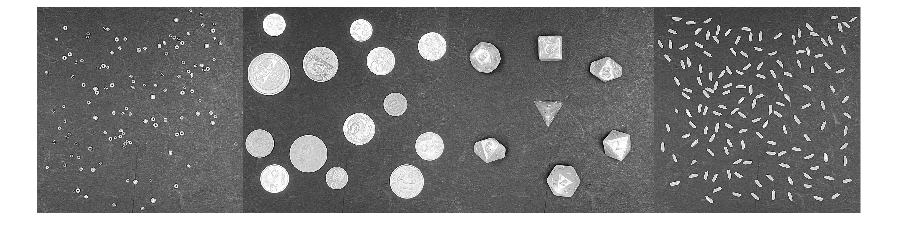

%opening the images and converting them to grayscale
beads_orig = imread('beads_7.png');
coins_orig = imread("coins_7.png");
dice_orig = imread('dice_7.png');
rice_orig = imread('rice_7.png');
beads = rgb2gray(beads_orig);
coins = rgb2gray(coins_orig);
dice = rgb2gray(dice_orig);
rice =rgb2gray(rice_orig);

montage([beads, coins, dice, rice], 'Size', [1 NaN]);

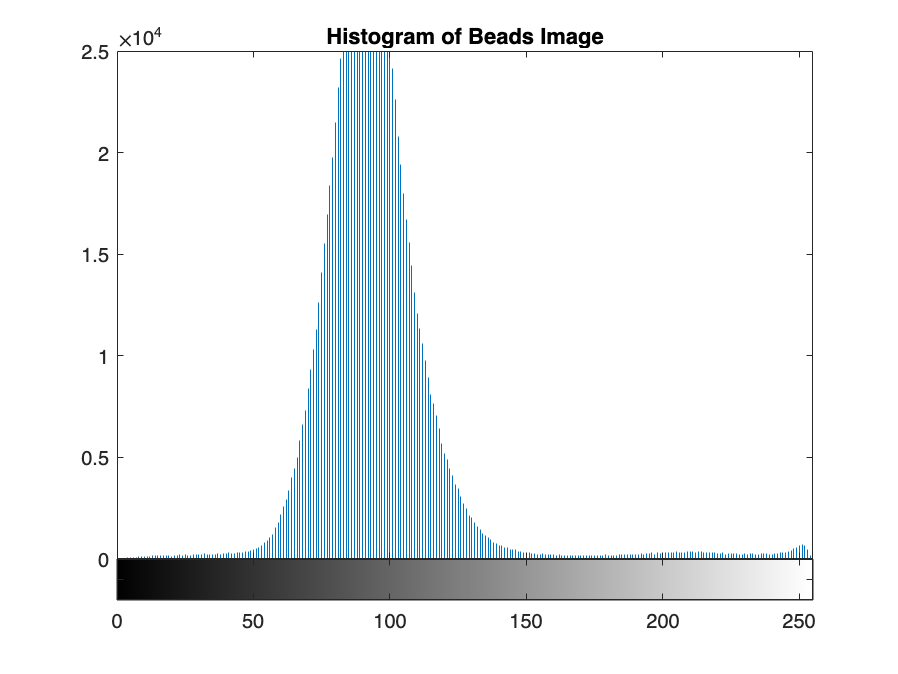

%gettiing the histograms 
figure; imhist(beads); title('Histogram of Beads Image');

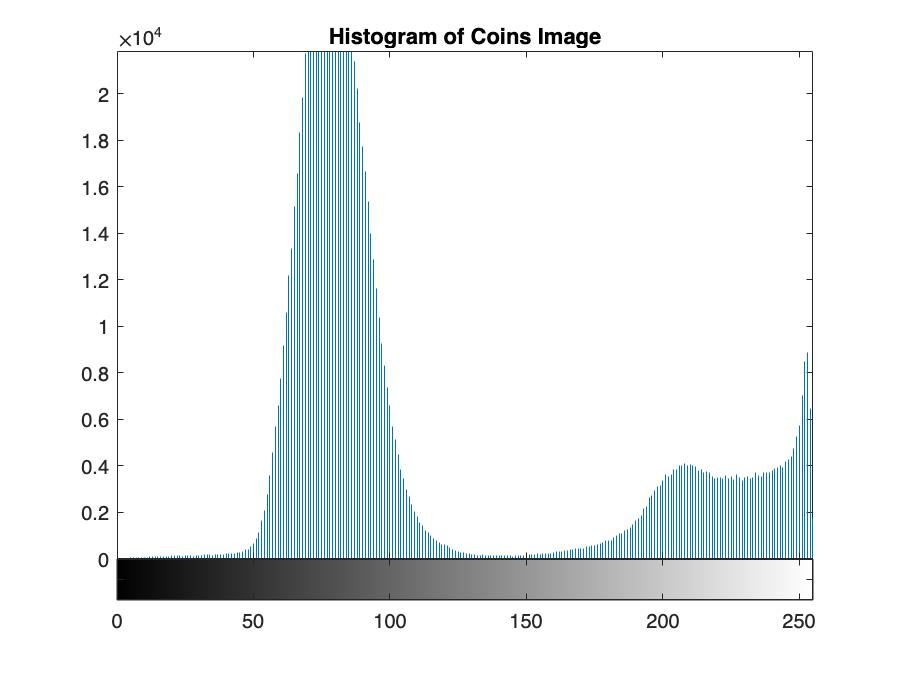

figure; imhist(coins); title('Histogram of Coins Image');

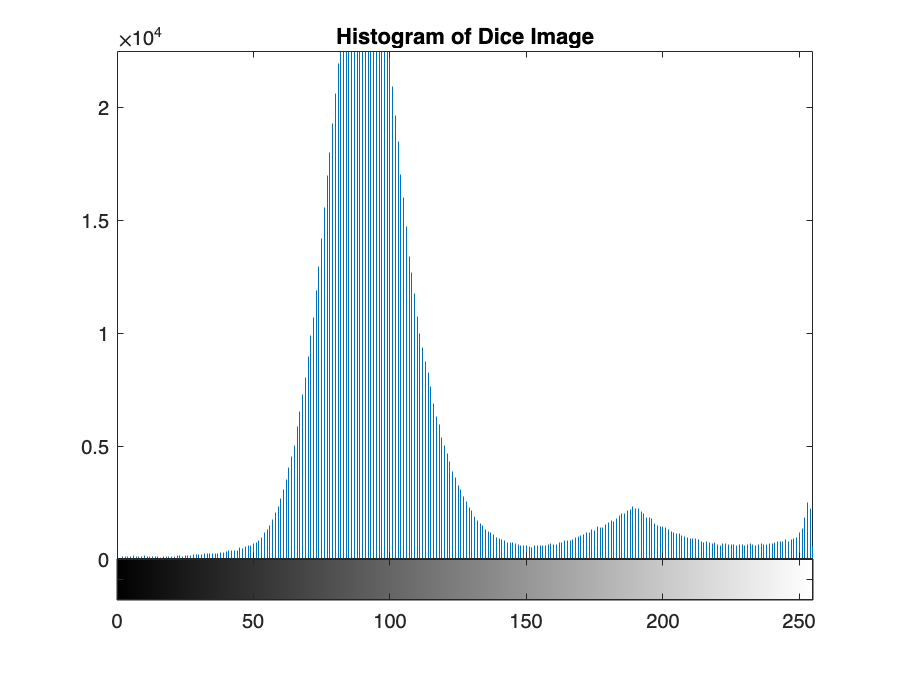

figure; imhist(dice); title('Histogram of Dice Image');

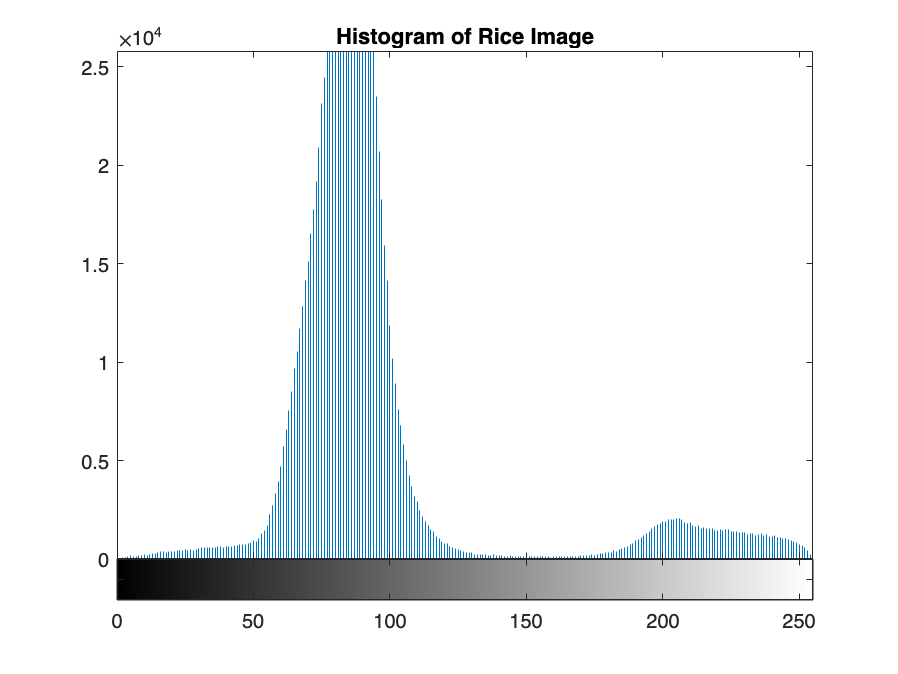

figure; imhist(rice); title('Histogram of Rice Image');

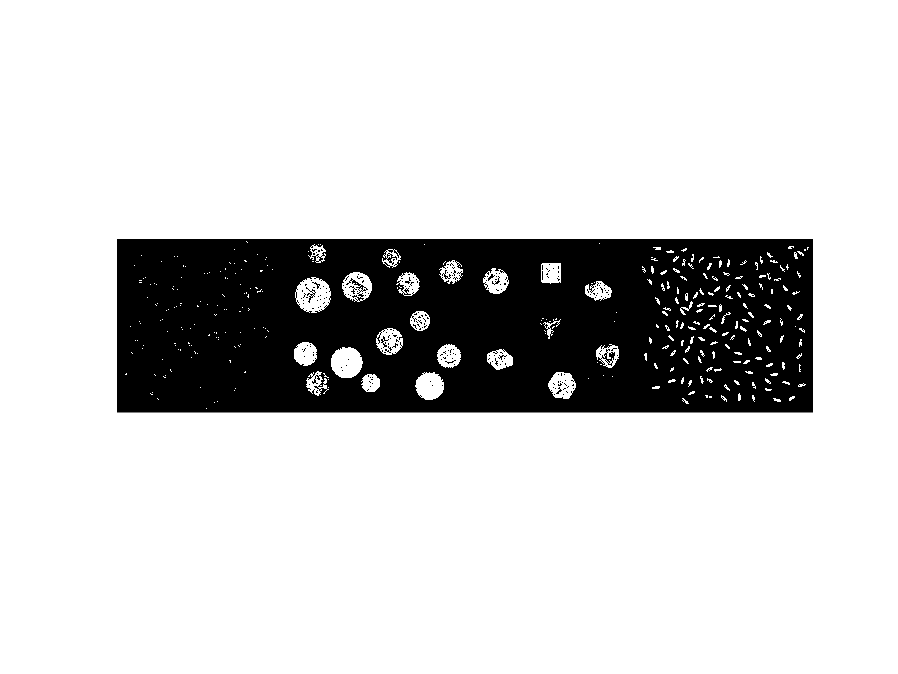

%thresholding
beads_thrsh = and(beads < 250, beads > 225);
%imshow(beads_thrsh)
coins_thrsh = and(coins < 250, coins > 181);
%imshow(coins_thrsh)
dice_thrsh = and(dice < 250, dice > 170);
%imshow(dice_thrsh)
rice_thrsh = and(rice < 250, rice > 190);
%imshow(rice_thrsh)
montage([beads_thrsh, coins_thrsh, dice_thrsh, rice_thrsh], 'Size', [1 NaN]);

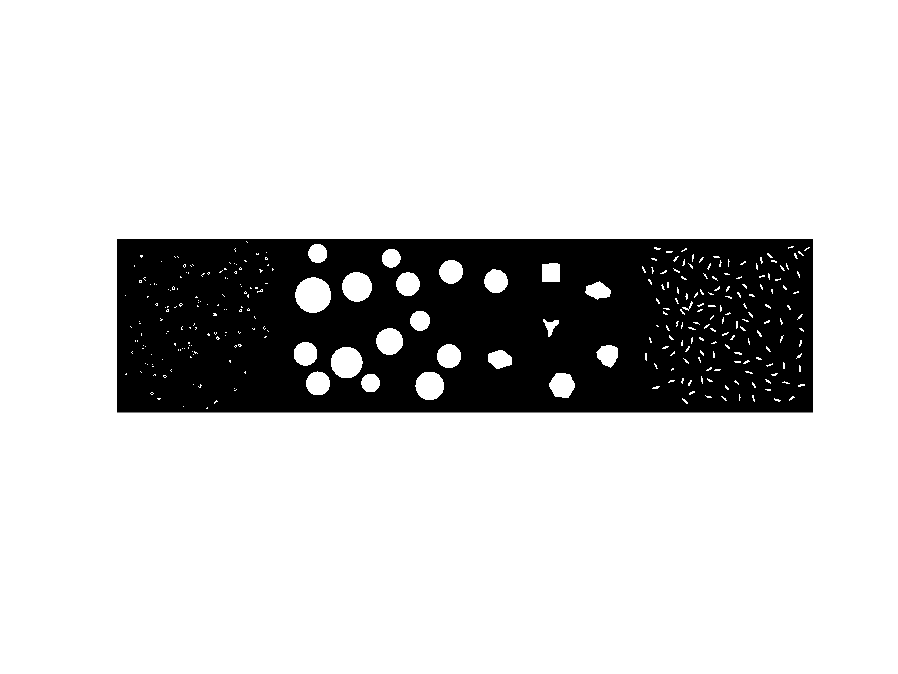

%cleaning
%beads
bw_beads = bwmorph(beads_thrsh, 'close');
bw_beads = bwmorph(bw_beads, 'thick');
%imshow(bw_beads)

%coins
bw_coins = imclose(coins_thrsh, strel('disk',12));
bw_coins =  imfill(bw_coins, 'holes');
bw_coins =  bwmorph(bw_coins, 'open');
%imshow(bw_coins)

%dice
bw_dice = bwmorph(dice_thrsh, 'open');
bw_dice = bwmorph(bw_dice, 'thin');
bw_dice = bwmorph(bw_dice, 'majority');
bw_dice = imfill(bw_dice, 'holes');
bw_dice = imclose(bw_dice, strel('disk', 35));
bw_dice = bwmorph(bw_dice, 'clean');
bw_dice = imerode(bw_dice, strel('disk', 5));
%imshow(bw_dice);

%rice
bw_rice = bwmorph(rice_thrsh, 'close');
bw_rice = bwmorph(bw_rice, 'thin');
bw_rice =  imfill(bw_rice, 'holes');
bw_rice = imerode(bw_rice, strel('disk', 1));
% imshow(bw_rice);
montage([bw_beads, bw_coins, bw_dice, bw_rice], 'Size', [1 NaN]);

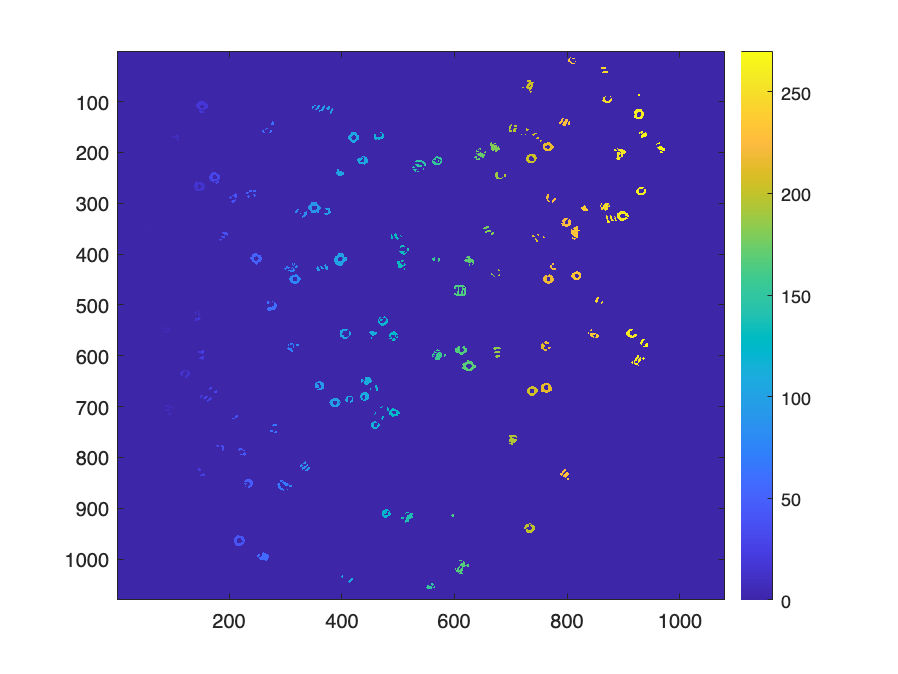

%putting labels
bw_beads_label = bwlabel(bw_beads); imagesc(bw_beads_label); colorbar;

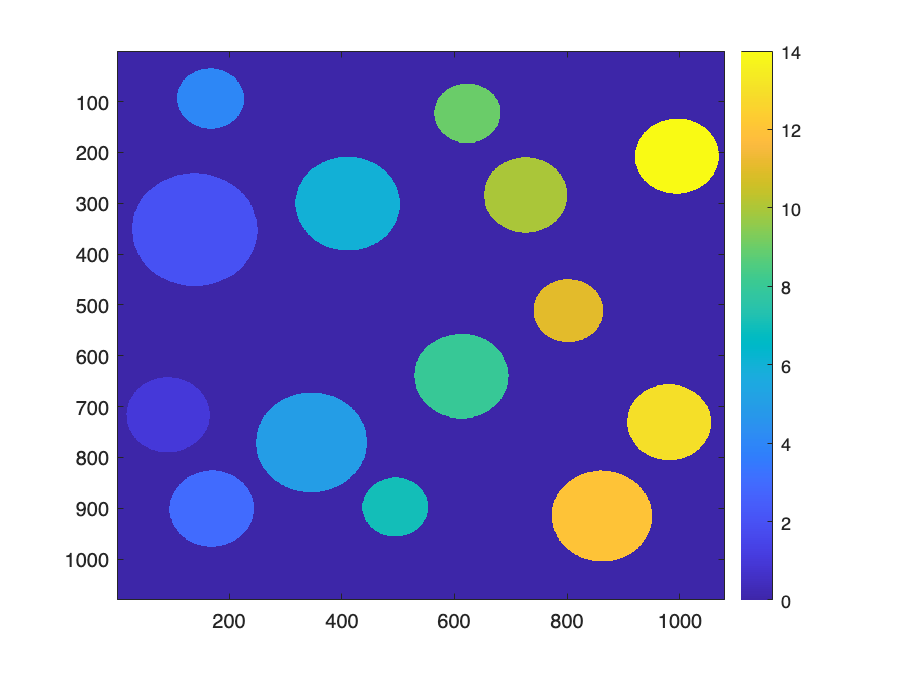

bw_coins_label = bwlabel(bw_coins); imagesc(bw_coins_label); colorbar;

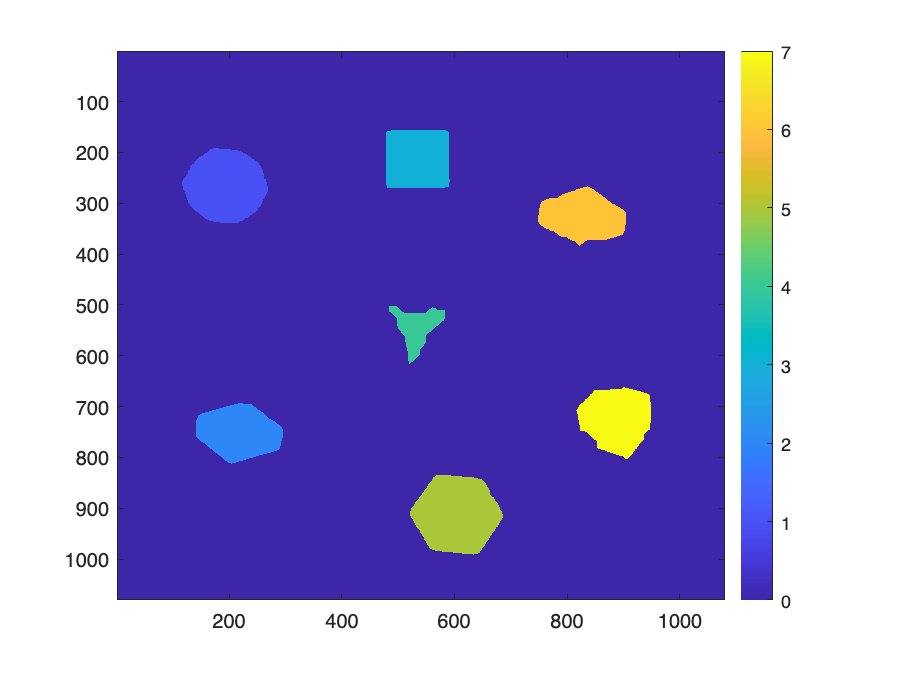

bw_dice_label = bwlabel(bw_dice); imagesc(bw_dice_label); colorbar;

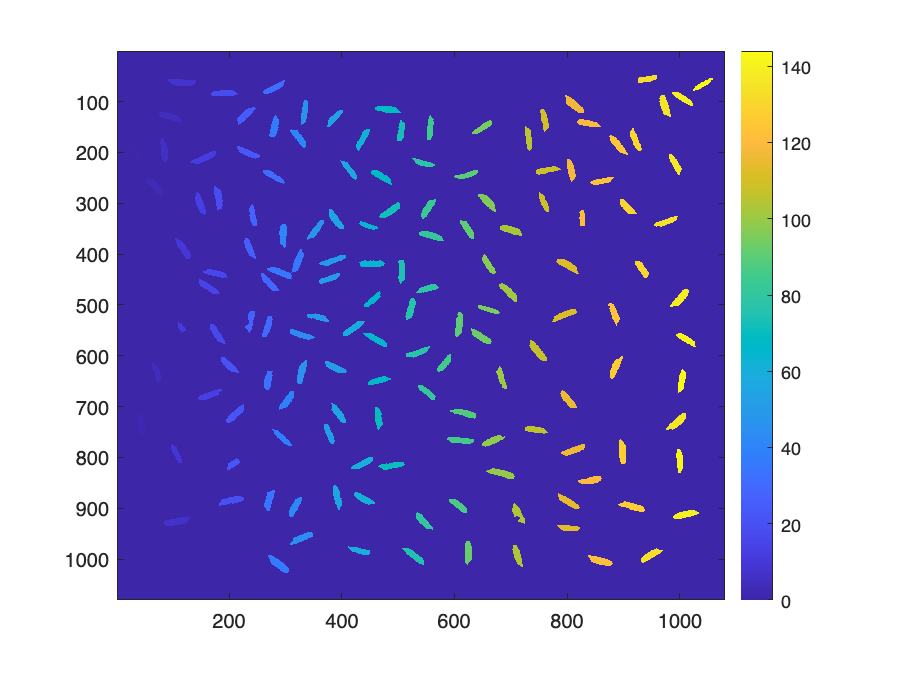

bw_rice_label = bwlabel(bw_rice); imagesc(bw_rice_label); colorbar;

% regionprops
ftr_beads = regionprops(bw_beads_label);
ftr_beads_table = struct2table(struct(ftr_beads))

ftr_beads_table = 270×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    175     57.149    841.45     48.5    833.5       17       16
     21     54.476    338.29     50.5    336.5        8        4
     14     54.143    353.07     51.5    351.5        5        3
     12     77.333    542.67     75.5    540.5        4        4
     29         85    545.52     81.5    542.5        7        6
     47     90.255    550.45     84.5    544.5       10       10
     65     93.508    700.42     85.5    697.5       15        7
     36     91.028    707.17     86.5    704.5        9        5
     30     93.933    714.83     90.5    712.5        7        5
     16     99.812    169.19     97.5    166.5        4        5
     43     107.19    169.26    103.5    165.5        8        7
     13     108.38    

ftr_coins = regionprops(bw_coins_label);
ftr_coins_table = struct2table(struct(ftr_coins))

ftr_coins_table = 14×3 table
    Area         Centroid                  BoundingBox           
    _____    ________________    ________________________________

    17151    91.046     716.2     16.5    642.5      149      147
    38832    138.58    351.93     27.5    240.5      223      222
    17578    168.87     900.8     93.5    825.5      151      150
    11059    166.76     94.02    106.5     34.5      120      119
    30332       346    770.26    247.5    672.5      197      196
    26865    410.33    300.71    317.5    208.5      186      184
    10701    494.98     897.7    436.5    839.5      117      116
    21857    612.35    639.84    528.5    556.5      168      167
    10823    622.78    122.81    563.5     64.5      118      117
    17274    726.36    283.93    652.5    209.5      148      149
    12045    802.28    511.26    740.5    449.5      124      124
    25022 

ftr_dice = regionprops(bw_dice_label);
ftr_dice_table = struct2table(struct(ftr_dice))

ftr_dice_table = 7×3 table
    Area         Centroid                  BoundingBox           
    _____    ________________    ________________________________

    16969    193.18    265.96    116.5    191.5      153      148
    13002    216.95    750.95    140.5    693.5      154      119
    12758    534.26    212.96    477.5    155.5      114      115
     4997     533.2    545.26    483.5    502.5      101      114
    18991    603.79    912.38    520.5    834.5      166      157
    12264    827.64    325.84    748.5    266.5      157      117
    13574     887.6       725    816.5    661.5      133      142


ftr_rice = regionprops(bw_rice_label);
ftr_rice_table = struct2table(struct(ftr_rice))

ftr_rice_table = 144×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    443     31.029    194.42     19.5    173.5       25       41
    516     43.874    735.11     36.5    711.5       14       47
    453     68.784    267.21     52.5    251.5       30       35
    383      71.29    633.24     62.5    613.5       17       39
    456     94.908    129.83     74.5    120.5       42       20
    438     84.527     196.8     77.5    172.5       14       47
    569     106.64    926.05     83.5    916.5       48       19
    521     116.47    62.347     91.5     55.5       49       14
    336     106.31    793.26     96.5    774.5       20       37
    503     118.46    389.77    103.5    368.5       28       42
    160     114.97    544.42    108.5    534.5       15       18
    514     155.62     

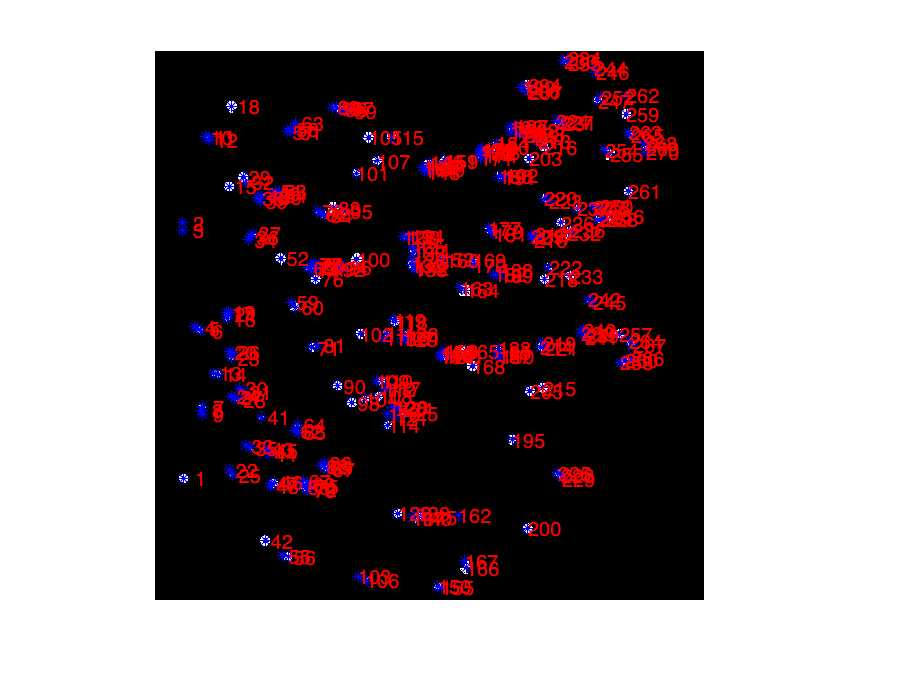

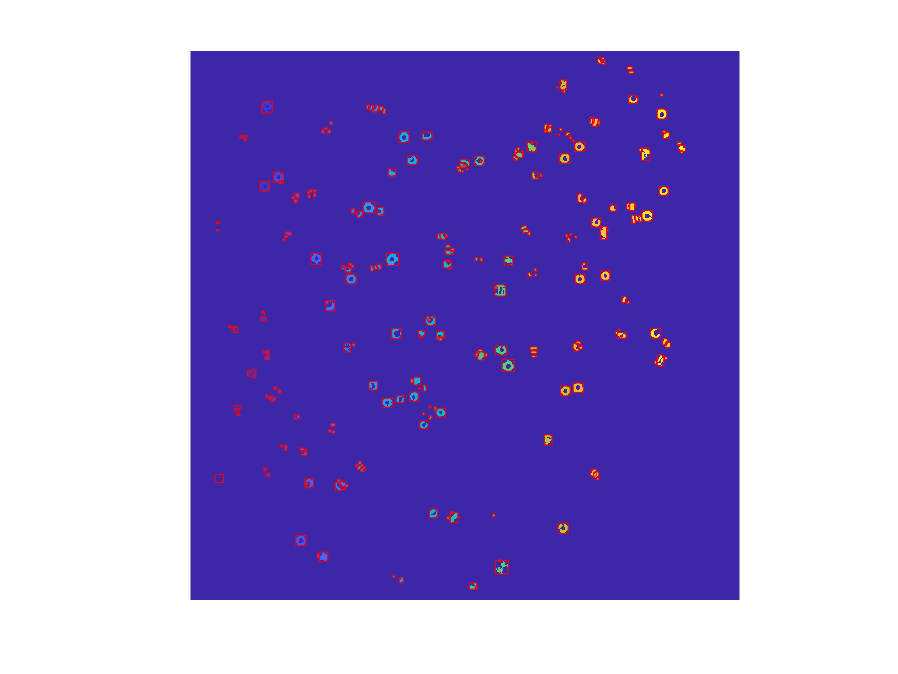

beads_properties = properties(bw_beads_label,ftr_beads);

stats_beads = statistical_properties(bw_beads_label)

Area Statistics:
Mean: 63.3185
Standard Deviation: 73.629
Perimeter Statistics:
Mean: 27.9395
Standard Deviation: 22.3761
Eccentricity Statistics:
Mean: 0.70272
Standard Deviation: 0.23476


stats_beads = 270×1 struct array with fields:
    Area
    Eccentricity
    Perimeter


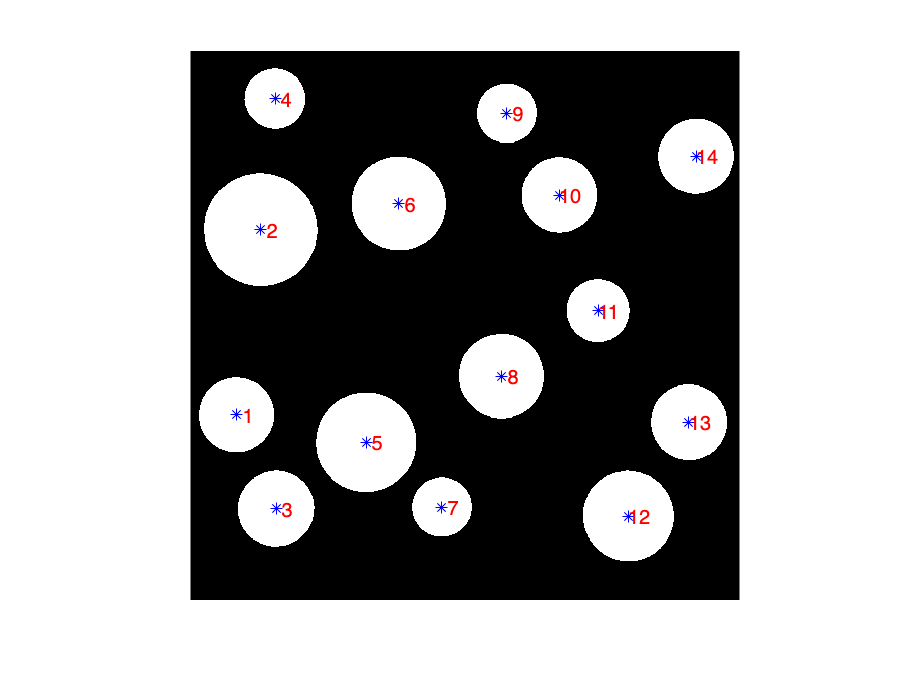

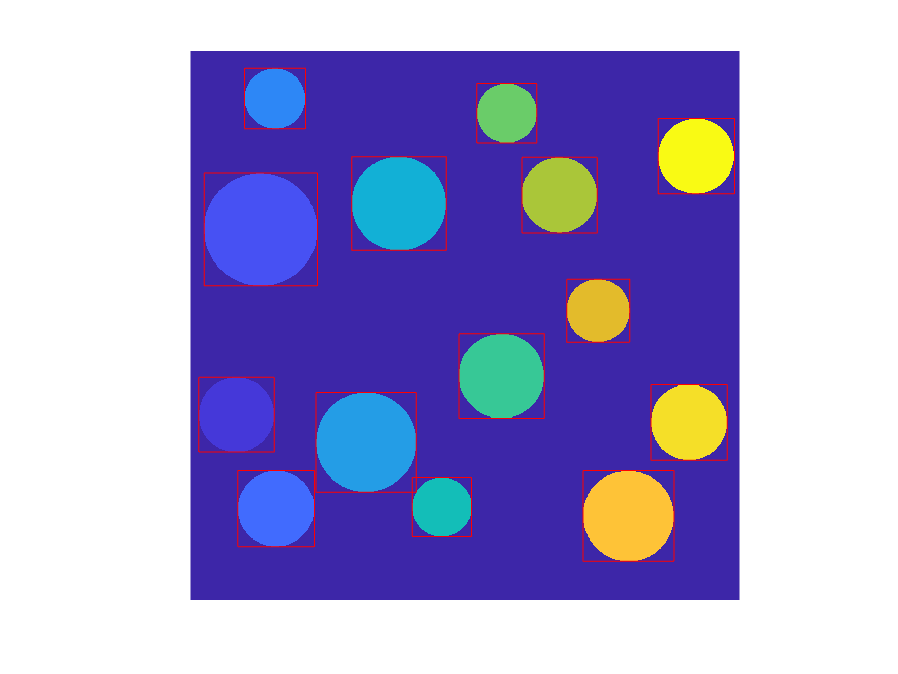

coins_properties = properties(bw_coins_label,ftr_coins);

stats_coins = statistical_properties(bw_coins_label)

Area Statistics:
Mean: 19597.7857
Standard Deviation: 8244.5217
Perimeter Statistics:
Mean: 484.6009
Standard Deviation: 100.3123
Eccentricity Statistics:
Mean: 0.12118
Standard Deviation: 0.027241


stats_coins = 14×1 struct array with fields:
    Area
    Eccentricity
    Perimeter


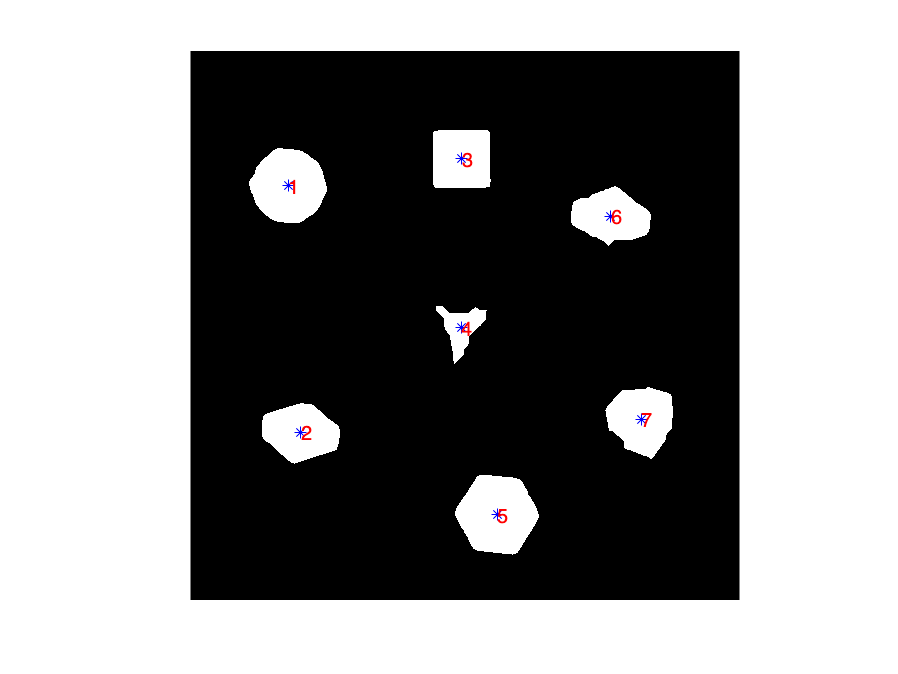

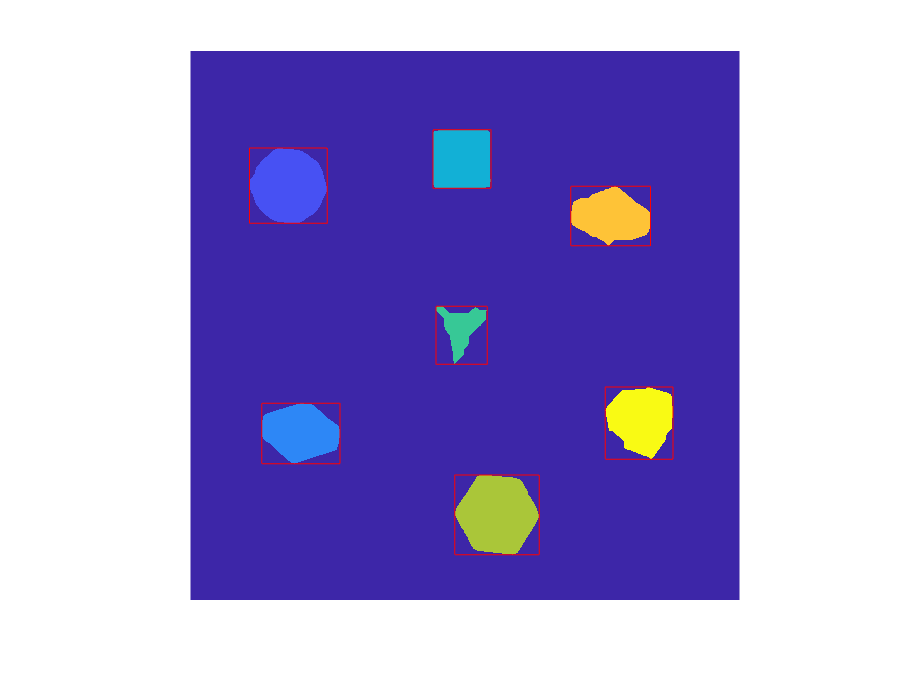

dice_properties = properties(bw_dice_label,ftr_dice);

stats_dice = statistical_properties(bw_dice_label)

Area Statistics:
Mean: 13222.1429
Standard Deviation: 4402.2221
Perimeter Statistics:
Mean: 437.1339
Standard Deviation: 41.825
Eccentricity Statistics:
Mean: 0.4129
Standard Deviation: 0.26573


stats_dice = 7×1 struct array with fields:
    Area
    Eccentricity
    Perimeter


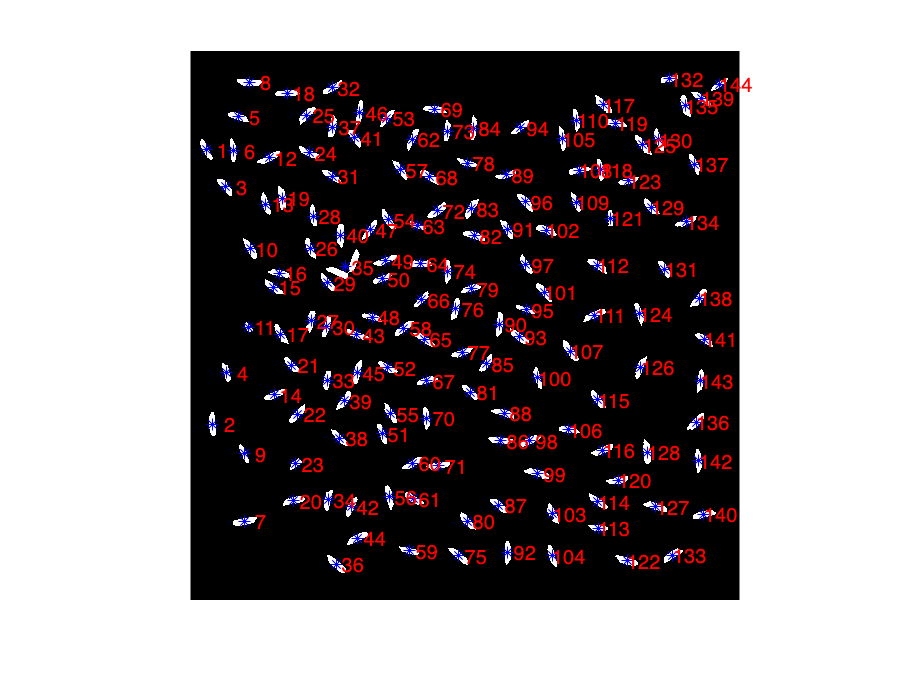

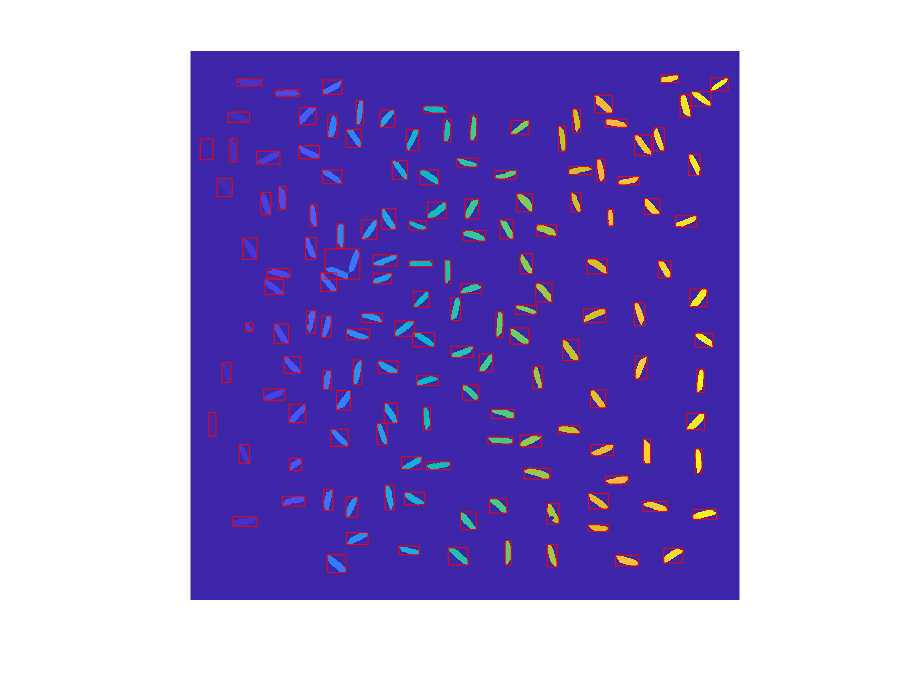

rice_properties = properties(bw_rice_label,ftr_rice);

stats_rice = statistical_properties(bw_rice_label)

Area Statistics:
Mean: 455.0625
Standard Deviation: 76.1278
Perimeter Statistics:
Mean: 98.3675
Standard Deviation: 12.6493
Eccentricity Statistics:
Mean: 0.95751
Standard Deviation: 0.012901


stats_rice = 144×1 struct array with fields:
    Area
    Eccentricity
    Perimeter


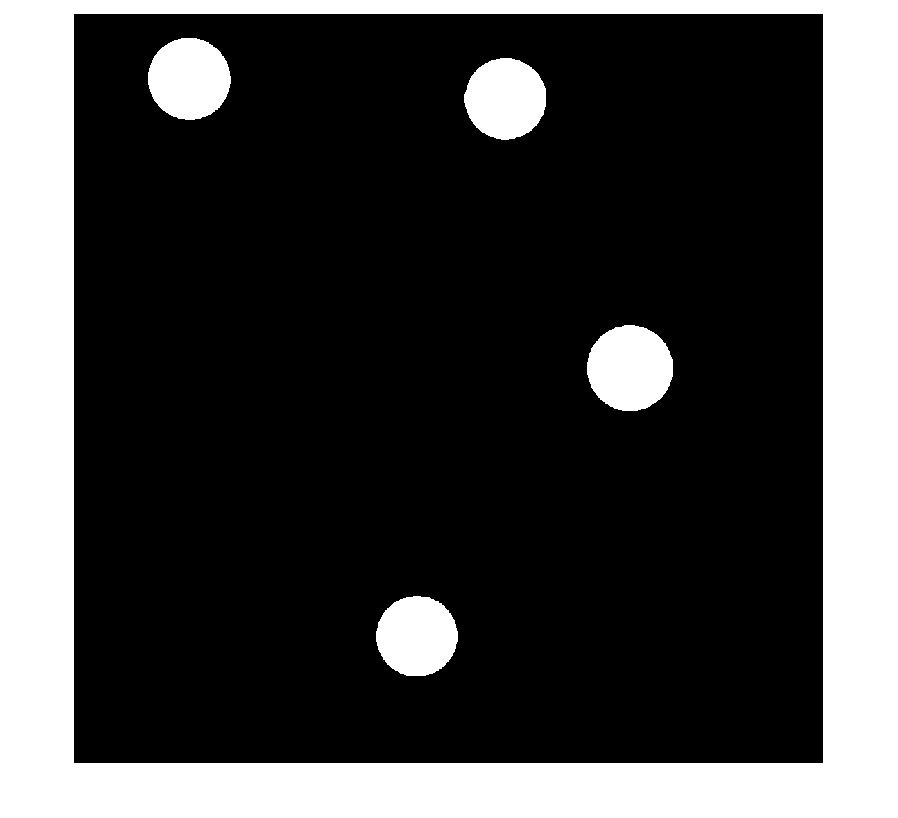

%regionprops but limited
stats_coins_5cents = regionprops(bw_coins_label, 'Area'); 
idx = find([stats_coins_5cents.Area] > 10000 & [stats_coins_5cents.Area] < 13000); 
coins_cents = ismember(bw_coins_label,idx);  
figure; imshow(coins_cents); axis image;
saveas(gcf,'coins_cents.jpeg')

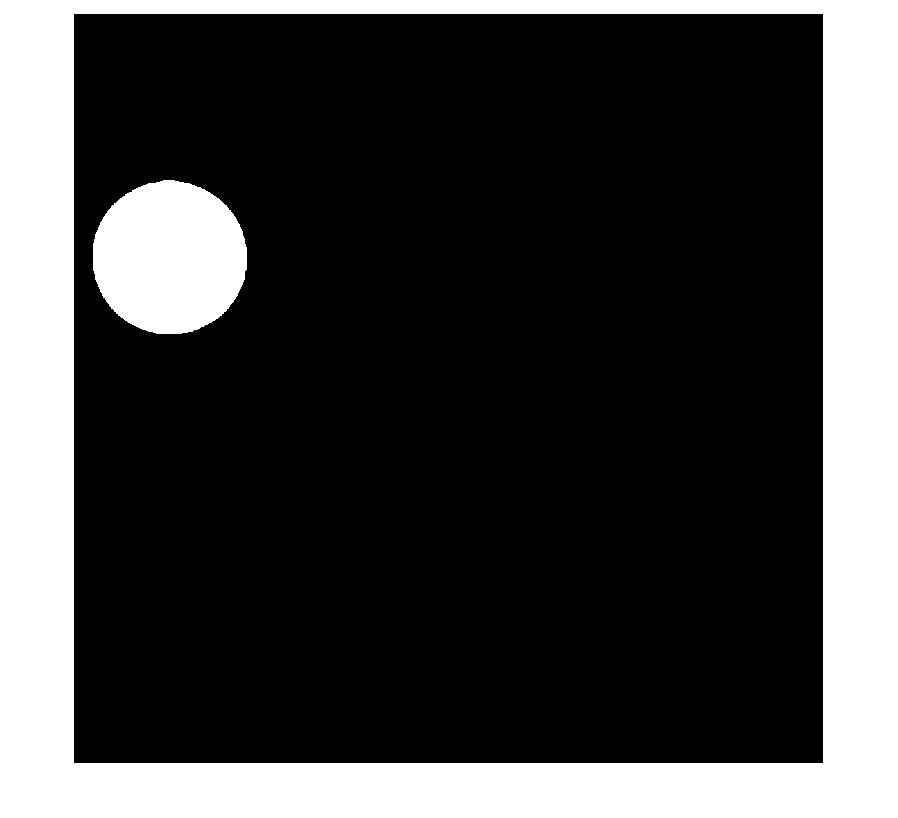


stats_coins_20 = regionprops(bw_coins_label, 'Area'); 
idx = find([stats_coins_20.Area] > 35000 & [stats_coins_20.Area] < 40000); 
coins_20 = ismember(bw_coins_label,idx);  
figure; imshow(coins_20); axis image;
saveas(gcf,'coins_20.jpeg')

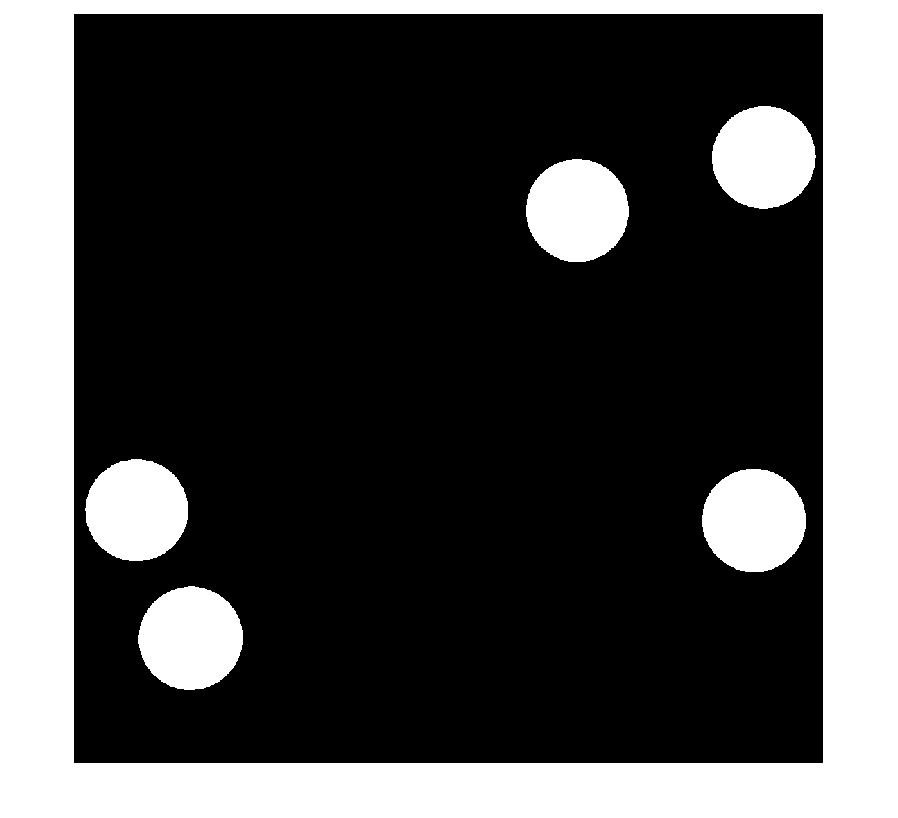



stats_coins_25 = regionprops(bw_coins_label, 'Area'); 
idx = find([stats_coins_25.Area] > 16000 & [stats_coins_25.Area] < 18000); 
coins_25 = ismember(bw_coins_label,idx);  
figure; imshow(coins_25); axis image;
saveas(gcf,'coins_25.jpeg')

%properties
function centroid = properties(image, x)
    centroid = cat(1, x.Centroid);
    imshow(image);
    hold on;
    plot(centroid(:,1), centroid(:,2), 'b*');
    
    % Add label numbers to centroids
    labels = 1:size(centroid, 1);
    text(centroid(:, 1), centroid(:, 2), num2str(labels'), 'Color', 'red');
    
    hold off;

    figure(); imagesc(image); hold on; axis off; axis image; 
    bounding_box = cat(1,x.BoundingBox);
    for i= 1:size(x,1);
        rectangle('Position', bounding_box(i,:), 'EdgeColor', 'r');
    end
end

function stats = statistical_properties(bwlabel);
    stats = regionprops(bwlabel, 'Area', 'Perimeter', 'Eccentricity');

    %area statistics
    areas = [stats.Area];
    mean_area = mean(areas);
    std_area = std(areas);

    %calculate perimeter stats
    perimeters= [stats.Perimeter];
    mean_perimeter = mean(perimeters);
    std_perimeter = std(perimeters);

    %eccentricity stats
    eccentricities = [stats.Eccentricity];
    mean_eccentricity = mean(eccentricities);
    std_eccentricity = std(eccentricities);

    % Display the statistics
    disp('Area Statistics:');
    disp(['Mean: ' num2str(mean_area)]);
    disp(['Standard Deviation: ' num2str(std_area)]);
    disp('Perimeter Statistics:');
    disp(['Mean: ' num2str(mean_perimeter)]);
    disp(['Standard Deviation: ' num2str(std_perimeter)]);
    disp('Eccentricity Statistics:');
    disp(['Mean: ' num2str(mean_eccentricity)]);
    disp(['Standard Deviation: ' num2str(std_eccentricity)]);

end





